Counting Steps:

clear
load('ActivityLogsforTesting.mat');
lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

% We use the following to obtain linear time data in seconds from a datetime array
positionTime=timeElapsed(positionDatetime);
accelTime=timeElapsed(accelDatetime);


earthCirc = 24901;
totaldis = 0;


for i = 1:(length(lat)-1)
    lat1 = lat(i);     % The first latitude
    lat2 = lat(i+1);   % The second latitude
    lon1 = lon(i);     % The first longitude
    lon2 = lon(i+1);   % The second longitude
    degDis = distance(lat1, lon1, lat2, lon2);
    dis = (degDis/360)*earthCirc;
    totaldis = totaldis + dis;
end


stride = 2.5;                   % Average stride (ft)
totaldis_ft = totaldis*3280.84;    % Converting distance from kilometers to feet
steps = totaldis_ft/stride;

disp(['The total distance traveled is: ', num2str(totaldis),' kilometers'])

The total distance traveled is: 8.753 kilometers


disp(['You took ', num2str(steps) ' steps'])

You took 11486.8193 steps


Test Data

load('ActivityLogsforTesting.mat');
load('TrainedModel.mat');

justAcc = timetable2table(Acceleration, "ConvertRowTimes", false);
yfit = trainedModel.predictFcn(justAcc)

yfit = 19844×7 char array
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sitting'
    'sit

Creating Graphics:

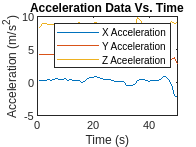

plot(justAcc,"X");
hold on;
plot(justAcc,"Y"); 
plot(justAcc,"Z");
xlim([0 50])
legend('X Acceleration','Y Acceleration','Z Aceeleration');
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');
title('Acceleration Data Vs. Time');
hold off

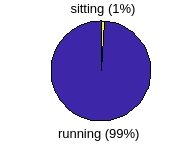

yfitcat = categorical(cellstr(yfit)); % convert to correct data type for histogram
pie(yfitcat)